clc; clear;

Enter Time axis as [start:step:stop]:

t = -5:0.1:5;

Enter the axis values as [d1 d2 ... dk] where the signal changes its shape/waveform:

disconts = [0 1 2];

Enter signal shape/waveform sections:

section_1 = 0*t;
section_2 =-sin(pi*(2-t));
section_3 = sin(pi*(2-t));
section_4 = 0*t;
sections = [section_1; section_2; section_3; section_4];

[a_signal, str ] = AperiodicSignal(AxisType.t,t,disconts,sections);
info = sprintf("%s",compose("signal shape/waveform sections :\n%s", str));
disp(info)

signal shape/waveform sections :
  t<0 , section_1
  0<=t<1 , section_2
  1<=t<2 , section_3
  t=>2 , section_4



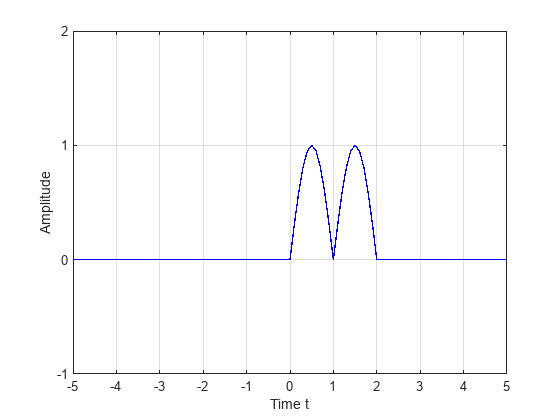

Draw(AxisType.t,t,a_signal)

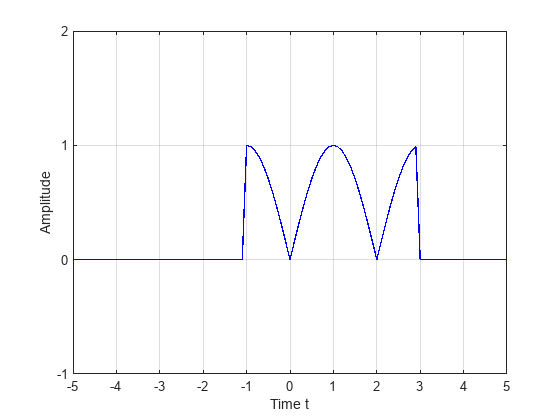

x = abs(sin(pi*t/2));
x1 = x.*(UnitStep(Sign.Positive,t,1) - UnitStep(Sign.Positive,t,-3));
Draw(AxisType.t,t,x1)

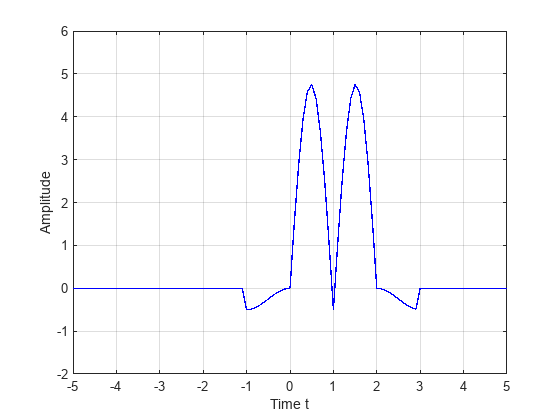

be = 5.*a_signal + -1.*x * 0.5.*x1;
Draw(AxisType.t,t,be)

Enter Samples axis as [start:1:stop]:

n = -35:1:35;

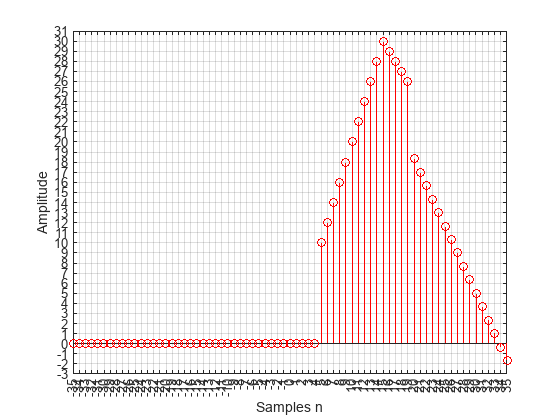

w = 2*n.*UnitStep(Sign.Positive,n,-5) -3*(n-15).*UnitStep(Sign.Positive,n,-15) +(-n./3).*UnitStep(Sign.Positive,n,-20);
Draw(AxisType.n,n,w)

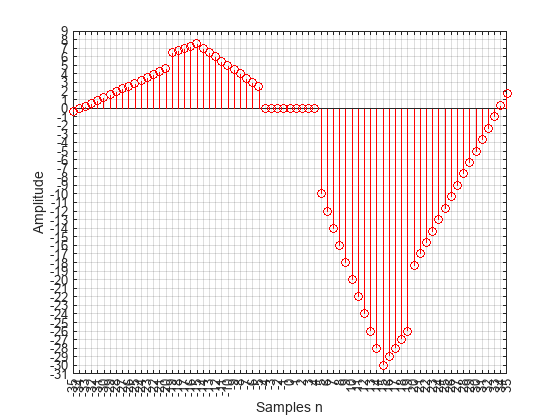

Draw(AxisType.n,n, -w +(0.25).*Reflect(w))

Ev{w[n]}

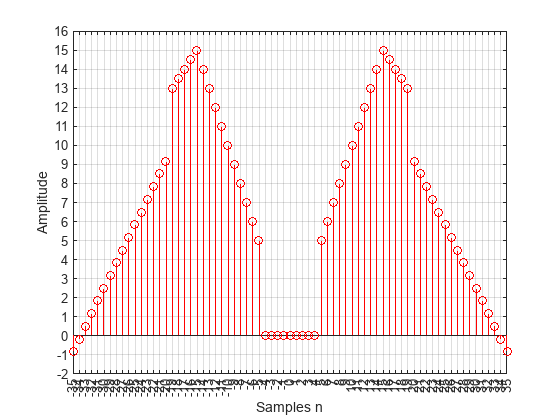

Draw(AxisType.n,n, 0.5*(w + Reflect(w)))

Odd{w[n]}

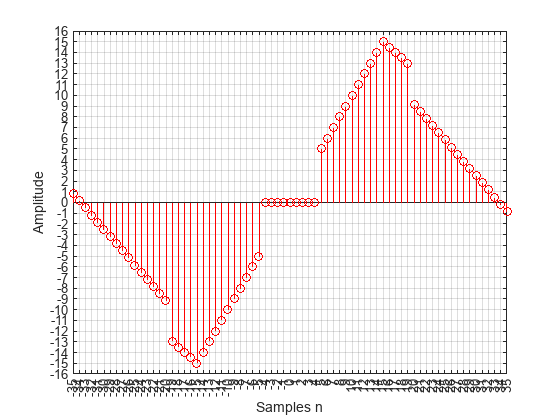

Draw(AxisType.n,n, 0.5*(w - Reflect(w)))

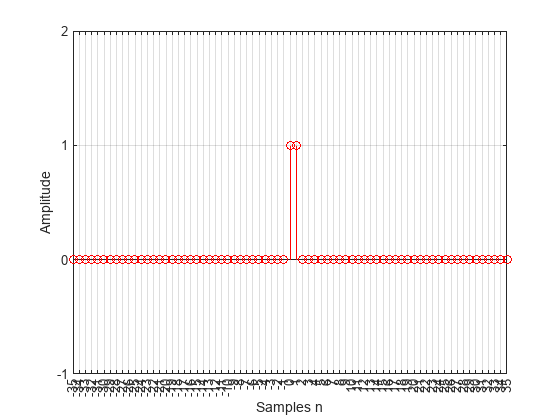

z = UnitImpulse(Sign.Positive,n,0) + UnitImpulse(Sign.Positive,n,-1);
Draw(AxisType.n,n,z)

Ev{z[n]}

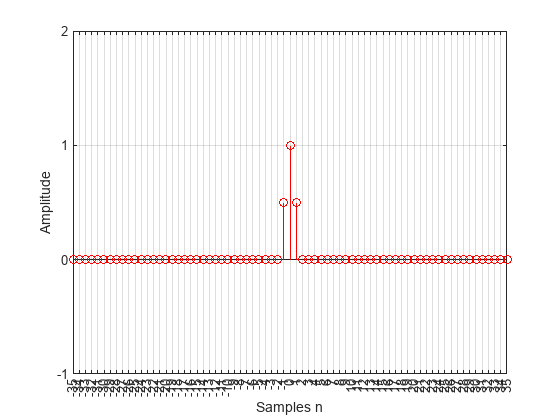

Draw(AxisType.n,n, 0.5*(z + Reflect(z)))

Odd{z[n]}

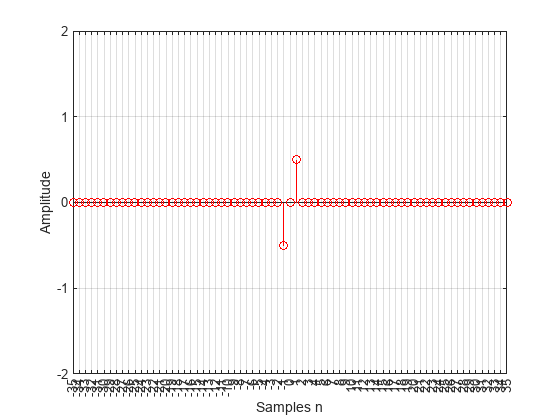

Draw(AxisType.n,n, 0.5*(z - Reflect(z)))

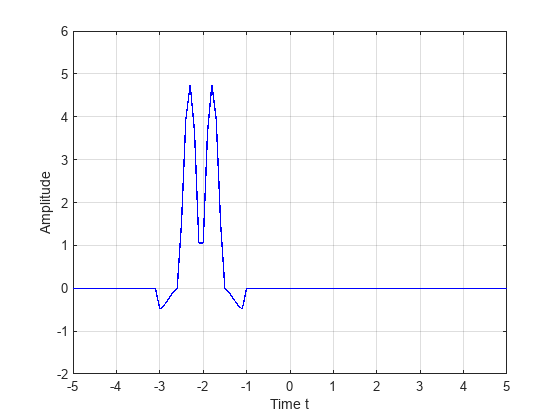

bes = ReScale(2, be);
Draw(AxisType.t,t,bes)